# Solution to the *A Forest of Trees *exercise

## 1. Complete the exercise “Credit Rating Classification” on page A - 12.

Load the data from `CreditData.mat` and extract the predictor variables `RE_TA`, `MVE_BVTD`, and `Industry` into a matrix.

load CreditData

FinRatios = [CreditRatings.RE_TA, ...
             CreditRatings.MVE_BVTD, ...
             CreditRatings.Industry];

Extract the `Rating` from the table and convert it to a categorical variable.

rnames = {'AAA','AA','A','BBB','BB','B','CCC'};
Ratings = categorical(CreditRatings.Rating,rnames);

Split data into training and validation sets to create a partition (80-20 split).

pt = cvpartition(Ratings,'holdout',0.2);

Extract predictors and responses for training and validation sets:

Ratings_t = Ratings(training(pt));
FinRatios_t = FinRatios(training(pt),:);
Ratings_v = Ratings(test(pt));
FinRatios_v = FinRatios(test(pt),:);

Create tree

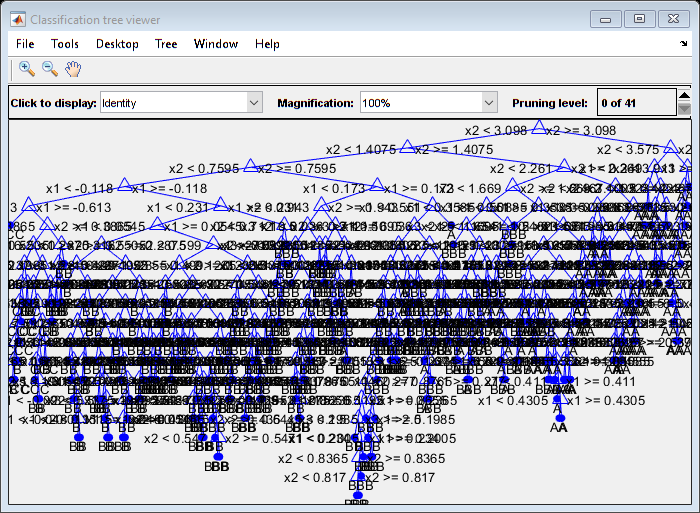

t = fitctree(FinRatios_t,Ratings_t);
view(t,'mode','graph')

Predict the credit ratings for the validation data and determine the validation error.

Ratings_Estimated = predict(t,FinRatios_v);
misclass = loss(t,FinRatios_v,Ratings_v);
disp(['Validation error for single tree: ',num2str(misclass)])

Validation error for single tree: 0.30407


## 2. Fit ensemble of trees

Create an ensemble of 100 classification trees with the original data.

tb = fitcensemble(FinRatios_t,Ratings_t,'Method','Bag','Learners','tree');

## 3. Predict

Predict the credit ratings with the ensemble and determine the misclassification rate.  How does this compare with the original model?

Ratings_Estimated2 = predict(tb,FinRatios_v);

Validation error

misclass2 = loss(tb,FinRatios_v,Ratings_v);
disp(['Validation error for ensemble: ',num2str(misclass2)])

Validation error for ensemble: 0.25829


## 4. Evaluate classification

Evaluate the classification by constructing a confusion matrix and visualize the groupings.

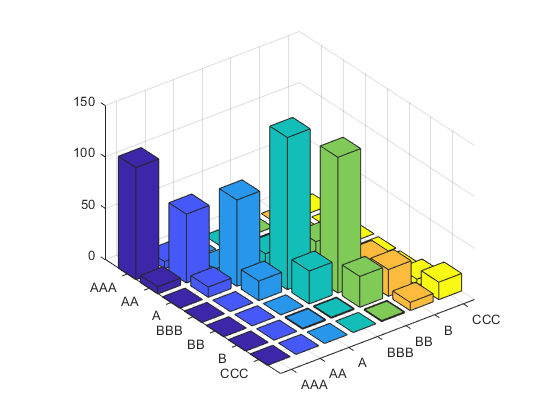

[c,lbls] = confusionmat(Ratings_v,categorical(Ratings_Estimated2));

bar3(c)
xticklabels(lbls);
yticklabels(lbls);

Create heatmap

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [7×1 categorical]

  Show all properties

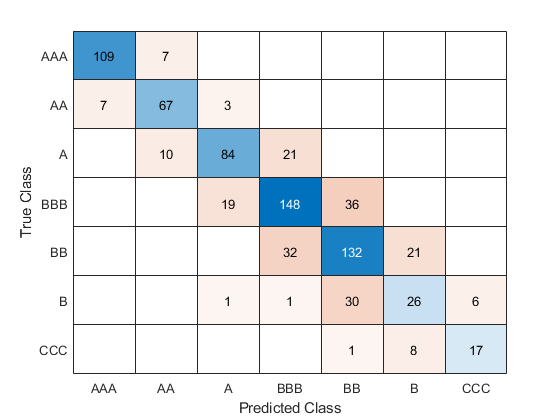

confusionchart(c,lbls)